# 3R Manipulator: Invers Kinematics 

This function is not functional, it is just to show ideas

clear

## Use a 3R from RTB model's

mdl_3link3d
joint_pose=[pi/6 pi/4 -pi/5]

joint_pose =     0.5236    0.7854   -0.6283


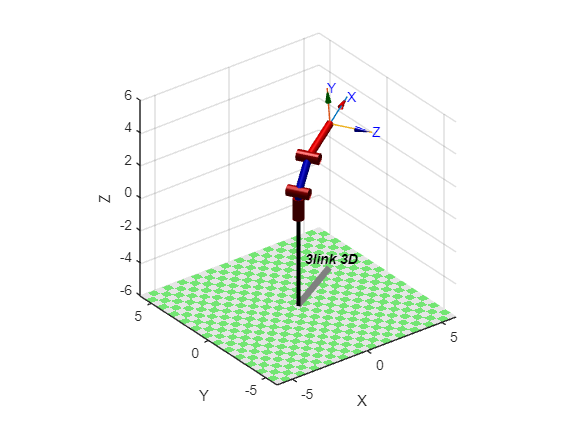

R3.plot(joint_pose)

### FK, given $\theta's$ get pose

Note Pose is a SE3 object

Pose=R3.fkine(joint_pose)

 

Pose = 
    0.8554   -0.1355    0.5000     3.791
    0.4938   -0.0782   -0.8660     2.189
    0.1564    0.9877         0     2.884
         0         0         0         1


Homogeneous transformation

HT=Pose.T

HT =     0.8554   -0.1355    0.5000    3.7908
    0.4938   -0.0782   -0.8660    2.1886
    0.1564    0.9877    0.0000    2.8835
         0         0         0    1.0000


Translational part, i.e. position

Position=Pose.t

Position =     3.7908
    2.1886
    2.8835


Orientation/Rotation matrix

Rotation=Pose.R

Rotation =     0.8554   -0.1355    0.5000
    0.4938   -0.0782   -0.8660
    0.1564    0.9877    0.0000


### IK, given  pose get $\theta's$

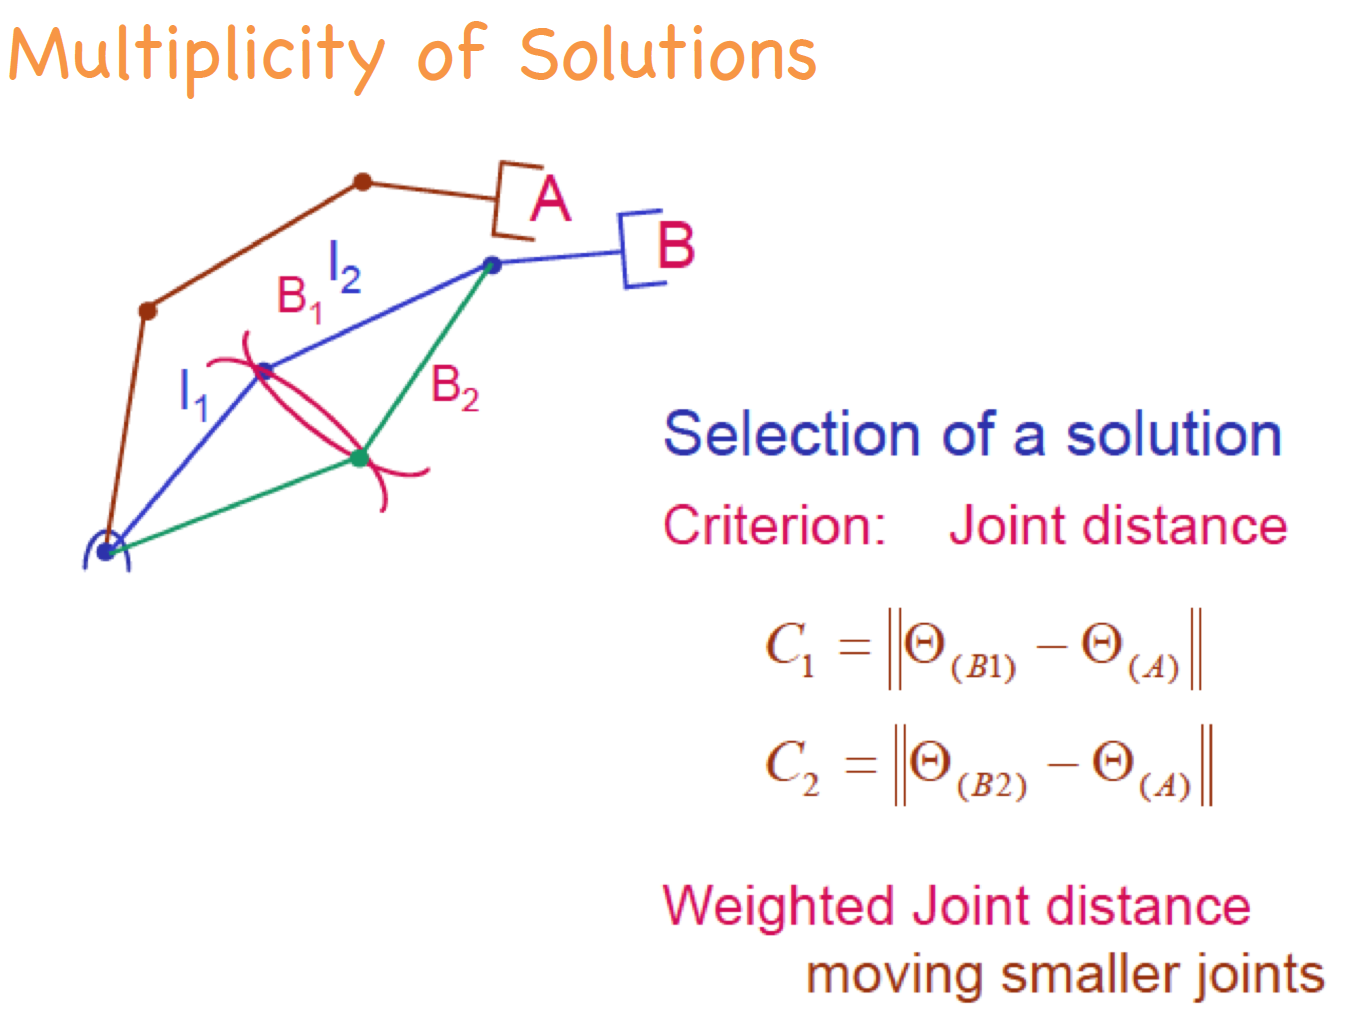

We impose the desired solution by telling to the function 'q0'

#### Elbown up solution

qq_up=R3.ikine(Pose,'mask',[1 1 1 0 0 0],'q0',[ 0 pi/2 0])

qq_up =     0.5236    0.7854   -0.6283


#### Elbown down solution

qq_down= R3.ikine(Pose,'mask',[1 1 1 0 0 0],'q0',[ 0 0 0])

qq_down =     0.5236    0.0273    0.6283


### Plotting elbown up/down solution

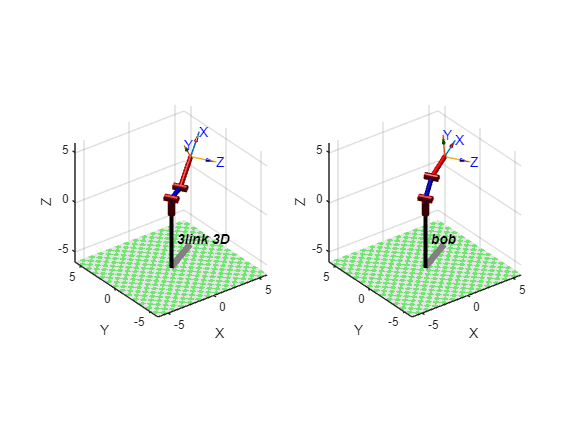

bob= SerialLink(R3, 'name', 'bob'); % clone R3
subplot (121)
R3.plot(qq_down)
subplot (122)
bob.plot(qq_up)

### Ckecking position

Notice: position are the same, Orientation differs

Pose_down=R3.fkine(qq_down)

 

Pose_down = 
    0.6865   -0.5280    0.5000     3.791
    0.3963   -0.3048   -0.8660     2.189
    0.6096    0.7927         0     2.884
         0         0         0         1


Pose

 

Pose = 
    0.8554   -0.1355    0.5000     3.791
    0.4938   -0.0782   -0.8660     2.189
    0.1564    0.9877         0     2.884
         0         0         0         1


## Ikine key idea: do it in RF {1}

Notice coordinate 'y'  of the {EE} = 0 and pose of the {EE} is wrt Reference frame {1}

We will work in the X/Z plane

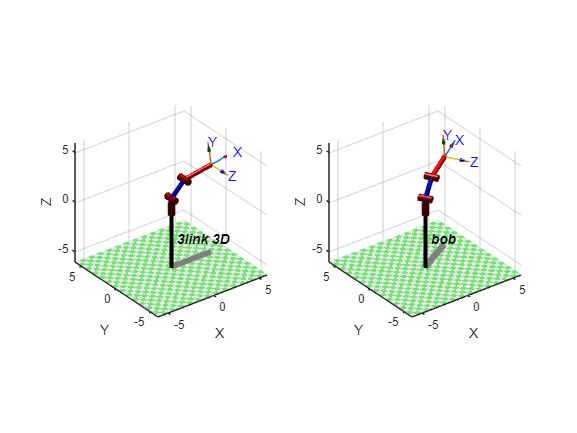

R3.plot(joint_pose -[qq_up(1) 0 0],'zoom',1.5)

Pose_1=R3.fkine(joint_pose -[qq_up(1) 0 0])

 

Pose_1 = 
    0.9877   -0.1564         0     4.377
         0         0        -1         0
    0.1564    0.9877         0     2.884
         0         0         0         1


## Implement 'ikine' function and compare with RTB

Take into consideration what we mention in Theory

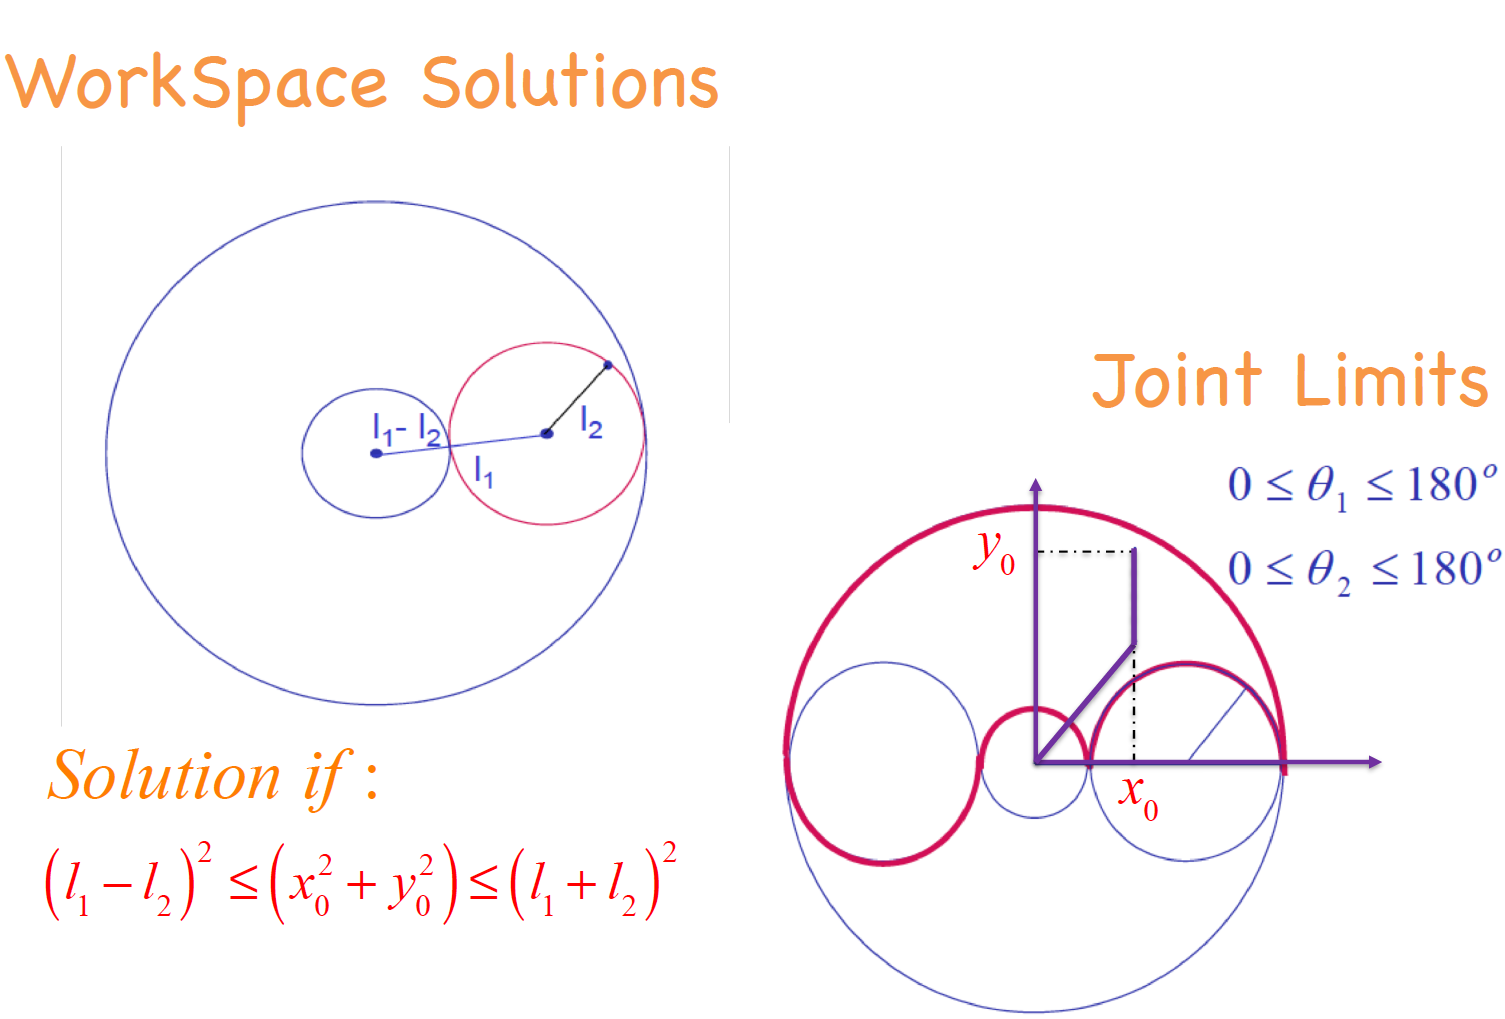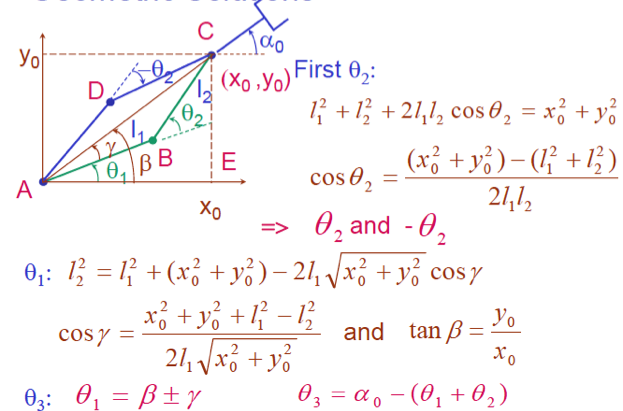

Q_down=inv_3R(Pose_down,0) % the implemented ikine

L122 = 22.7082

L1L2 = 25

L1_L2 = 1

Pose Recheable


Q_down =     0.5236    0.0273    0.6283


qq_down= R3.ikine(Pose,'mask',[1 1 1 0 0 0],'q0',[ 0 0 0]) % Using RTB 

qq_down =     0.5236    0.0273    0.6283


Q_up=inv_3R(Pose_down,1) % the implemented ikine

L122 = 22.7082

L1L2 = 25

L1_L2 = 1

Pose Recheable


Q_up =     0.5236    0.7854   -0.6283


qq_up=R3.ikine(Pose,'mask',[1 1 1 0 0 0],'q0',[ 0 pi/2 0]) % Using RTB  

qq_up =     0.5236    0.7854   -0.6283


NoReach=SE3([7 2 3])

 

NoReach = 
         1         0         0         7
         0         1         0         2
         0         0         1         3
         0         0         0         1


Q_up=inv_3R(NoReach,1)

L122 = 57

L1L2 = 25

L1_L2 = 1

Pose no Recheable


Q_up = NaN

## Inverse Kinematics function

function q=inv_3R(pose,ud)
% if ud=1 -> elbown up; ud=0 -> elbown down
% There will be two solutions:
% 1.- [q1  (q2=beta+gamma) -q3]; elbow up
% 2.- [q1  (q2=beta-gamma) +q3]; elbow down
% Robot DH Parameters
mdl_3link3d;
L0=R3.links(1, 1).d;
L1=R3.links(1, 2).a;
L2=R3.links(1, 3).a;
xyz=[pose.t;1];
% q1 is a solution, then q(1) + pi is also a solution
theta_1=atan2(xyz(2), xyz(1));
% Express xyz in the reference frame 1, notice coordinates y = 0
T_1_0=transl(0,0,L0)*trotz(theta_1);
xyz=inv(T_1_0)*[pose.t;1];
% Now it is a twolink InversKinematics
% Recover: Invers_Kinematics_Key_ideas.mlx
L122=(norm(xyz(1:3)))^2
L1L2=(L1+L2)^2
L1_L2=(L1-L2)^2
theta_3=acos(((xyz(1)^2+xyz(3)^2)-(L1^2+L2^2))/(2*L1*L2));
beta=atan2(xyz(3),xyz(1));
gamma=acos((xyz(1)^2+xyz(3)^2+L1^2-L2^2)/(2*L1*sqrt((xyz(1)^2+xyz(3)^2))));
theta_2_1=beta+gamma;
theta_2_2=beta-gamma;
q_aux=zeros(1,3);

if (L122 >= L1_L2) && (L122 <= L1L2)
   disp('Pose Recheable')
  if ud==1
     q_aux=[theta_1 theta_2_1 -theta_3]; 
  else
  if ud==0
     q_aux=[theta_1 theta_2_2 theta_3];
  end
  end
end
if (L122>L1L2)||(L122<L1_L2)
    disp('Pose no Recheable')
    q_aux=nan;
end
q=q_aux;
end